## Creating FIR and IIR filters (Notch filter, also known as bandstop filter)

A notch filter takes out specific frequencies from a signal, like below.

load data.mat
fs=102.4

fs = 102.4000

### 3a) Calculate where the 50Hz and -50Hz frequencies are located in the (complex) z-domain 						

z1 = exp(i*2*pi*50/fs) % 50 Hz

z1 = -0.9973 + 0.0736i

z2 = exp(-i*2*pi*50/fs) % -50 Hz

z2 = -0.9973 - 0.0736i

### 3b) Place a zero at each of these locations

syms z;
bsymb = expand((z-z1)*(z-z2)); 
b = sym2poly(bsymb)% polynomial with roots at z1 and z1

b =     1.0000    1.9946    1.0000


### 3c) Find the poles

The poles are between z = 0 and the zeros. Make their magnitude 0.9 times the magnitude of the zeros, find the denominator polynomial in a similar fashion and call its coefficients a.

magP = 0.9*abs(z1);
angP1 = angle(z1);
angP2 = angle(z2);

[a1,b1] = pol2cart(angP1,magP);
[a2,b2] = pol2cart(angP1,magP);

p1 = a1 + i*b1; % pole 1
p2 = a2 - i*b2; % pole 2

asymb = expand((z-p1)*(z-p2)); 
a = sym2poly(asymb)

a =     1.0000    1.7951    0.8100


### 3d) Inspect your filter with freqz

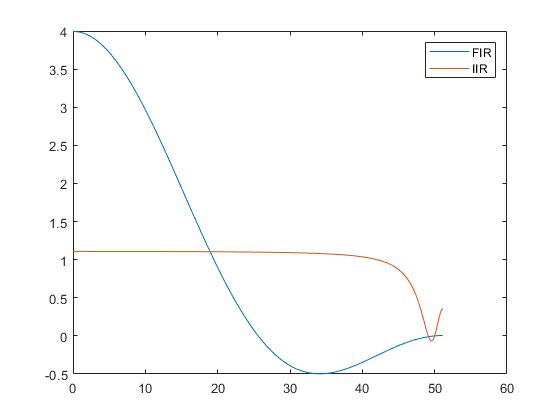

FIR = freqz(b,1,[],fs);
IIR = freqz(b,a,[],fs);
f = (0:length(FIR)-1)*(fs/(2*length(FIR)));
plot(f,FIR)
hold on
plot(f,IIR)
hold off
legend("FIR","IIR")

### 3e) Filter corrupted signal

Then use your filter to filter the corrupted signal d1. Try it by only using a FIR filter (the coefficients b only) and the using a IIR filter (the coefficients b and a).

% Filter corrupted signal d1 
d1FIR = filter(b,1,d1);
d1IIR = filter(b,a,d1);

and compare your filtered signal, the corrupted signal and the original uncorrupted signal.  What are the differences between the IIR and FIR filters? Why?

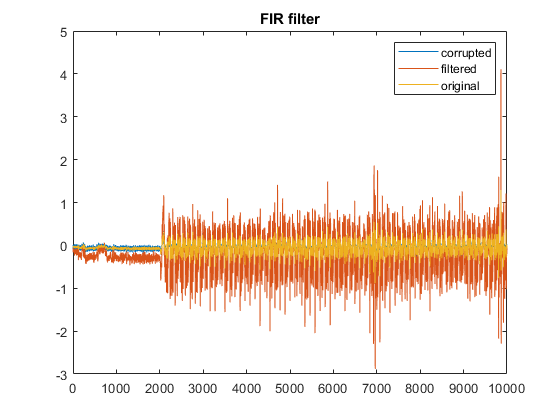

% plot corrupted, filtered and original data
figure;
tiledlayout(1,2)
% plot corrupted signal, FIR results and original signal
plot((1:length(d1)),d1)
hold on
plot((1:length(d1)),d1FIR)
hold on
plot((1:length(d1)),data)
hold off
legend({'corrupted','filtered','original'});
title('FIR filter')
nexttile

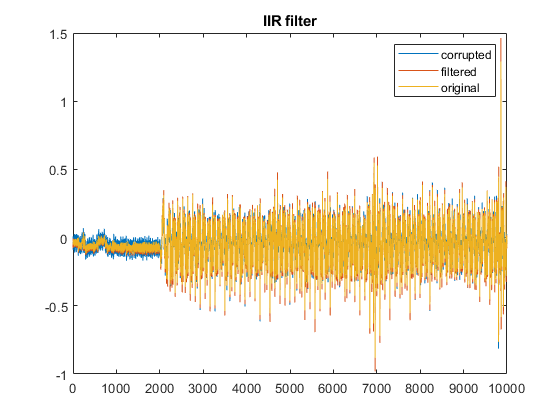

% plot corrupted signal, IIR results and original signal
plot((1:length(d1)),d1)
hold on
plot((1:length(d1)),d1IIR)
hold on
plot((1:length(d1)),data)
hold off
legend({'corrupted','filtered','original'});
title('IIR filter')